# Descriptors per cada senyal

Per atacar el problema, volem veure les caracterísitques mes rellevants de cada

## Color

Els colors son força significatius per totes les senyals. Els colors principals a tractar son el blau, el groc i el vermell.

- Color més predominant

- Presència de colors

- Forma + Color

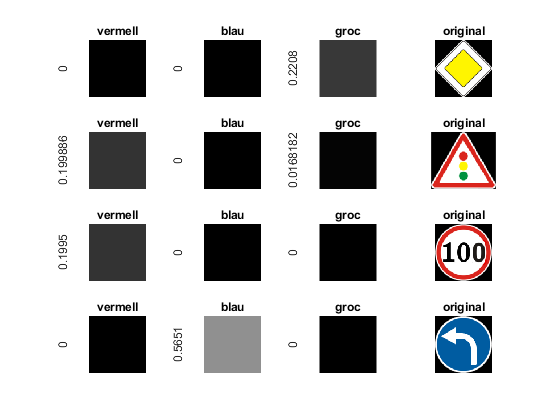

imagenes = [12, 26, 7, 34];

figure;
aux = 1;
numImatges = numel(imagenes);
descripcions = 4;
for iterador=1:numImatges
    iActual = imread(strcat("Models\Meta\", int2str(imagenes(iterador)),'.png'));
    [iRed, iBlue, iYellow] = calcColors(iActual);
    
    subplot(numImatges,descripcions,aux);
    imshow(iRed);title vermell;
    ylabel(iRed)
    
    subplot(numImatges,descripcions,aux+1);
    imshow(iBlue);title blau
    ylabel(iBlue)
    
    subplot(numImatges,descripcions,aux+2);
    imshow(iYellow);title groc;
    ylabel(iYellow)
    
    subplot(numImatges,descripcions,aux+3);
    imshow(iActual); title original;
    
    aux = aux + descripcions;
end

## Hough

Podem aplicar la transformada de Hough per reconeixer les rectes, pero comparant el rang de les pendents de les rectes, d'aquesta manera ens permet discriminar les senyals amb linies rectes com la senyal 9 o 32.

Podem considerar aquest valor amb un llindar, 1 per valors de rang < 8 i 0 per valors superiors.

calcParaleles(imread("Models\Meta\6.png"));
calcParaleles(imread("Models\Meta\1.png"));
calcParaleles(imread("Models\Meta\32.png"));
calcParaleles(imread("Models\Meta\41.png"));
calcParaleles(imread("Models\Meta\42.png"));

## Forma circular, triangular, rombo

Tenim molta informació amb la forma exterior de la senyal i el seu color.

Podem detecar les figures geomètriques bàsiques amb les propietats de les regions blanques, sumat a una detecció del color ens permet:

aquesta propietat la podem emmagatzemar com un 0 o 1 directament per no arrosegar una variable categórica.

- esCercleVermell

- esRomboBlanc

- esTriangleInvertitVermell

- esRomboideBlanc

- esCercleBlanc

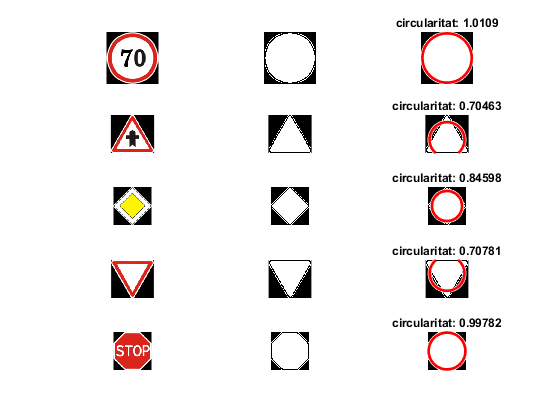

imagenes2 = [4, 11, 12, 13, 14];

figure;
aux = 1;
numImatges = numel(imagenes2);
descripcions = 3;

for iterador=1:numImatges
    img = imread(strcat("Models\Meta\", int2str(imagenes2(iterador)),'.png'));
    BW = rgb2gray(img);         %pasem a escala de grisos
    BW = edge(BW,'canny');      %resaltem les bores
    BW = imfill(BW, "holes");   %ens quedem amb la forma mes exterior
    
    stats = regionprops("table", BW,"all");
    [~,maxidx] = max(stats.Area);

    centers = stats.Centroid; 
    diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2); 
    radii = diameters/2;
    
    subplot(numImatges, descripcions, aux);
    imshow(img);
    
    subplot(numImatges,descripcions,aux+1);
    imshow(BW); 
    
    subplot(numImatges,descripcions,aux+2);
    imshow(BW); title(strcat("circularitat: ", num2str(stats.Circularity(maxidx))));
    hold on
    viscircles(centers(maxidx,:),radii(maxidx)); 
    hold off
    
    aux = aux + descripcions;
end